# Ionization rate profiles from energetic precipitation


alt = 40:1:160;
energyBin = [5, 30, 100, 300, 1000]*10^3;


A = get_energy_dep_matrix(alt',energyBin',[],[],datenum('01 Jan 2008'));

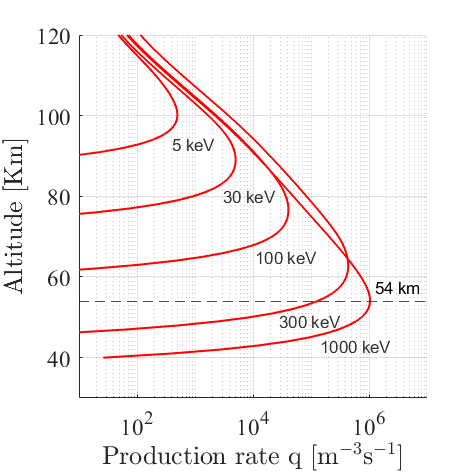

figureHandle = figure;
resize_figure(figureHandle,100,100);
q = A*diag(ones(1,length(energyBin)));
semilogx(q,alt,'Color','r','LineWidth',1.2);
xlim([10,10^7]);
ylim([30,120]);
set(gca,'FontName','Times','FontSize',14);
set(gca,'YTick',[40,60,80,100,120],'XTick',[10^2, 10^4, 10^6]);
box off;
ylabel('Altitude [Km]','Interpreter','latex','FontSize',14,'FontName','Times');
xlabel('Production rate q [m$^{-3}$s$^{-1}$]','Interpreter','latex','FontSize',14,'FontName','Times');
grid on;
hold on;
gray= [1,1,1].*0.2;
text(max(q(:,1))-100,93,'5 keV','Color',gray);
text(max(q(:,2))-2000,80,'30 keV','Color',gray);
text(max(q(:,3))-30000,65,'100 keV','Color',gray);
text(max(q(:,4))-410000,49,'300 keV','Color',gray);
text(max(q(:,5))-900000,43,'1000 keV','Color',gray);
% [~,I]=max(q(:,5));
yline(alt(I),'--k',[num2str(alt(I)),' km'],'LineStyle','--');
% yline(90,'--k');
% yline(70,'--k');
% yline(alt(I),'--k','1 MeV');

export_fig('G:\My Drive\Nithin\Job Search\JEPostDoc\Data\Final\Fig2_ionization.pdf','-r600','-pdf','-nocrop');